clear all; close all; clc;

load(fullfile("Data","wavelengths.mat"));
load(fullfile("Data","variableNames.mat"));

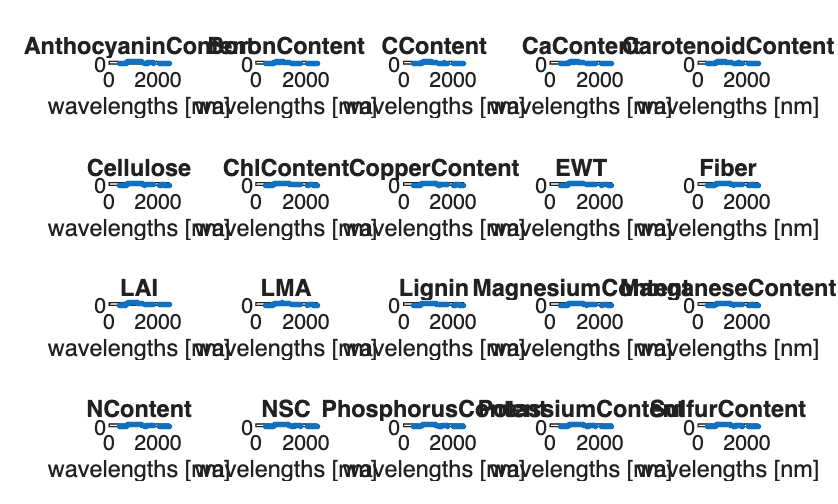

for i = 1:length(variables)
    load(fullfile("Data","splitDataset",variables(i)+".mat"));
    trait_avg(i) = mean(data(:,1));
    trait_std(i) = std(data(:,1));
    trait_size(i) = length(data(:, 1));
    trait_min(i) = min(data(:, 1));
    trait_max(i) = max(data(:, 1));
    
    avg_spectrum = mean(data(:, 2:end));
    nexttile; plot(wavelengths, avg_spectrum, '.');
    xlabel("wavelengths [nm]"); ylabel("Reflectance [a.u.]");
    title(extractBefore(variables(i), "_"));
end

headers = ["Trait", "Average", "Standard deviation", "N", "Min", "Max"]';
stat_prop = table(variables', trait_avg', trait_std', trait_size', trait_min', trait_max', 'VariableNames', headers);
mkdir(fullfile("Data","statistical_properties"))
save(fullfile("Data","statistical_properties", "stat_prop"));